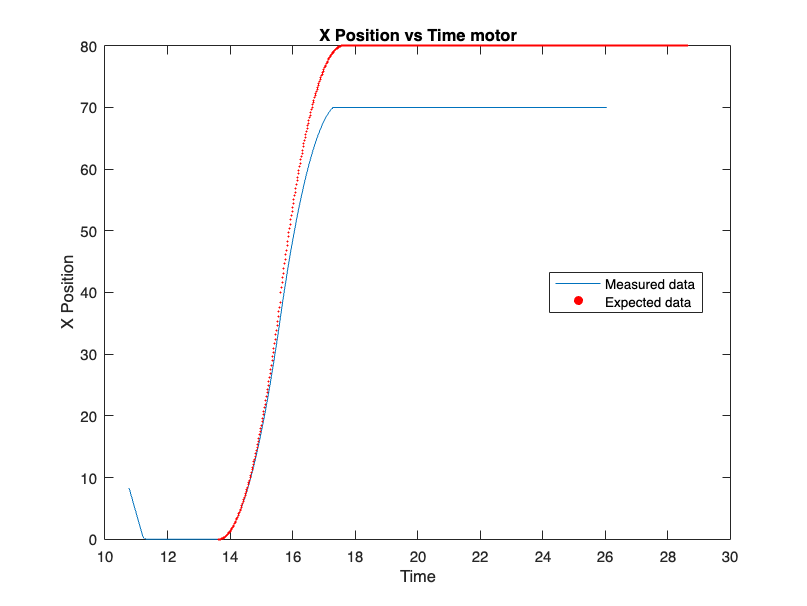

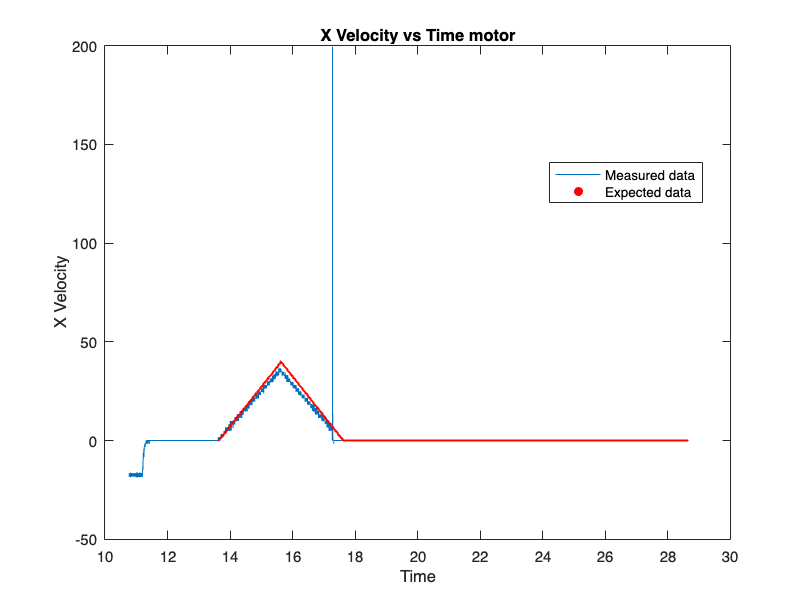

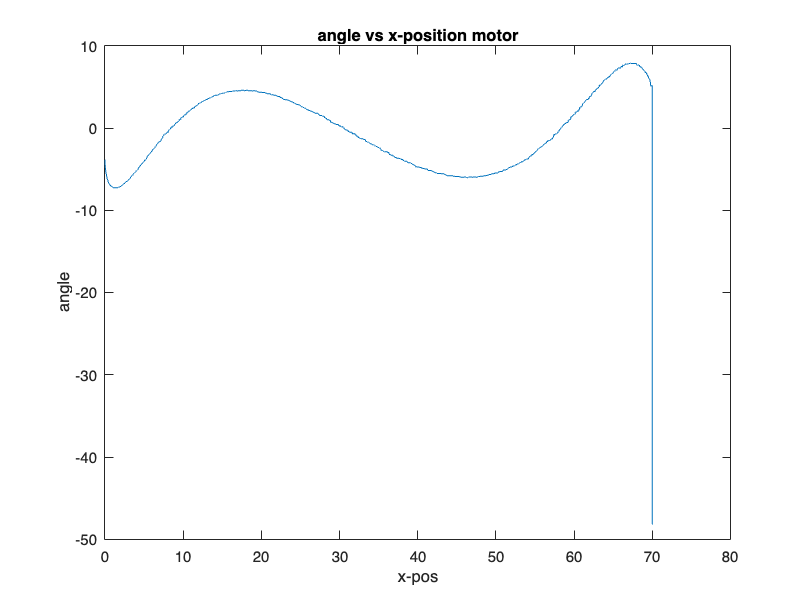

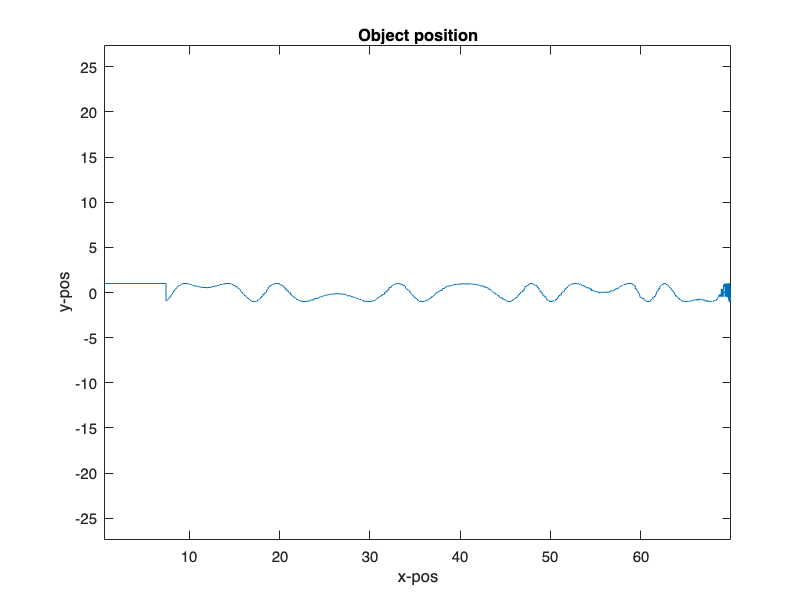

plot_1 = true;
plot_2 = true;
plot_3 = true;
plot_4 = true;
freq = 50;



if plot_4 == true
    % Define the file name
    file_name = 'bangbang_v02_no_angle_old.csv';
    
    % Read the CSV file
    data = csvread(file_name, 10000); % Skip the first 6000 rows
    
    % Extract time (1st column) and x position (4th column)
    time =  data(:,1);
    x_position = data(:, 4);
    x_velocity = data(:,5);
    angle = data(:, 15);
    y_position = data(:,6);
    last_zero_index = find(x_position == 0, 1, 'last');
    time_shift = time(last_zero_index);

    
    input_data = csvread("bangbang_position_old.csv");
    input_time = 1:length(input_data);
    input_position = input_data(1,:);
    input_data = csvread("bangbang_velocity_old.csv");
    input_velocity = input_data(1,:);


    figure;
    plot(time, x_position);
    xlabel('Time');
    ylabel('X Position');
    hold on 
    scatter(input_time/freq + time_shift, input_position*100, 2, 'r', 'filled');
    hold off
    title('X Position vs Time motor');
    legend('Measured data', 'Expected data', 'Location', 'best');


    figure;
    plot(time, x_velocity);
    xlabel('Time');
    ylabel('X Velocity');
    hold on 
    scatter(input_time/freq + time_shift, input_velocity*100, 2, 'r', 'filled');
    hold off
    title('X Velocity vs Time motor');
    legend('Measured data', 'Expected data', 'Location', 'best');
    
    

    figure
    plot(x_position(last_zero_index:end), angle(last_zero_index:end));
    xlabel('x-pos');
    ylabel('angle');
    title('angle vs x-position motor');
    

    figure
    plot(smoothdata(x_position +sin(angle)), cos(angle));
    xlabel('x-pos');
    ylabel('y-pos');
    title('Object position');
    axis equal

    
end

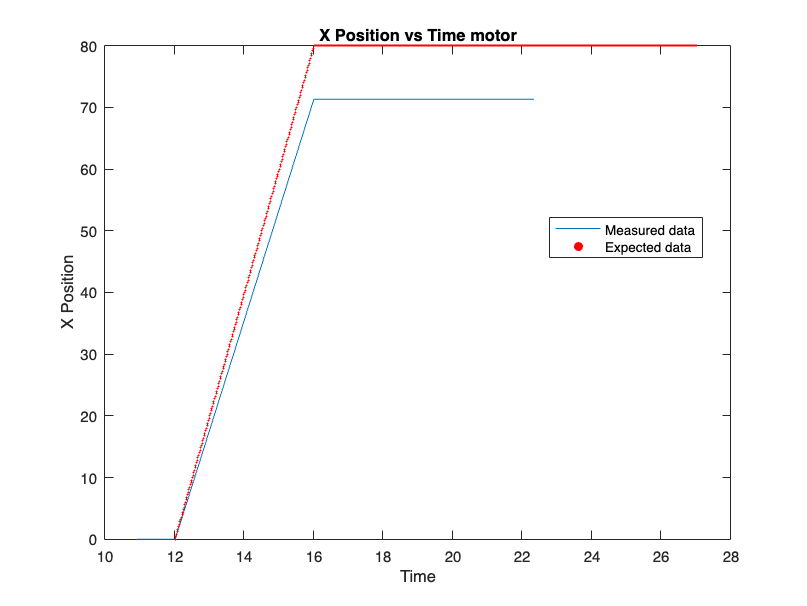

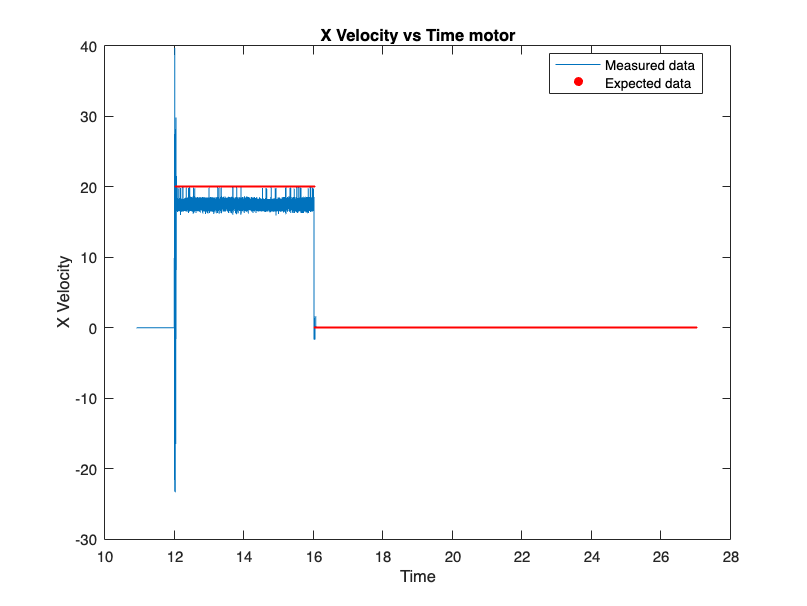

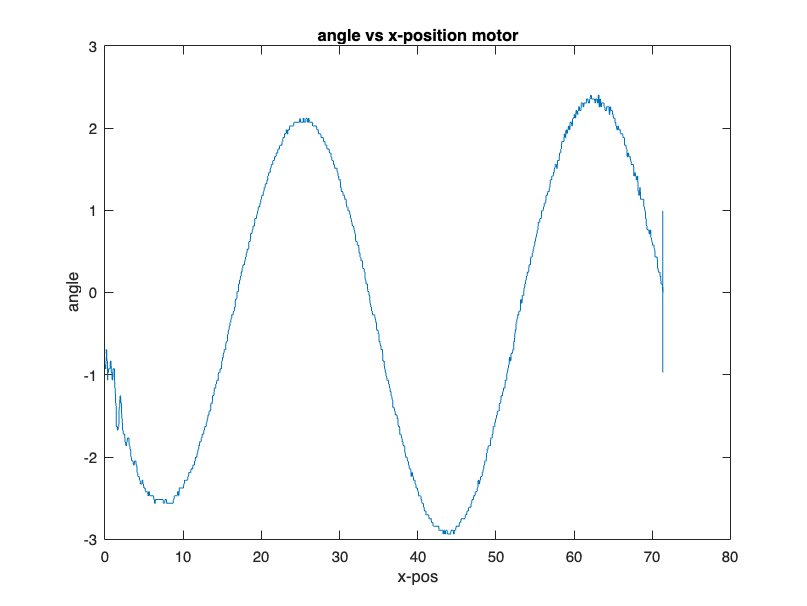

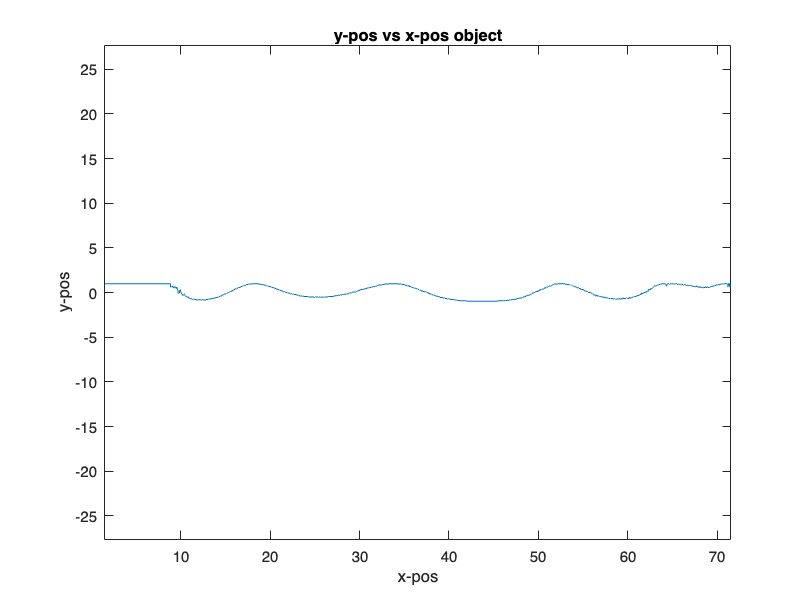




%%%%%%%%%


if plot_1 == true  
    % Define the file name
    file_name = 'ramp_v02_no_angle.csv';
    
    % Read the CSV file
    data = csvread(file_name, 10000); % Skip the first 6000 rows
    
    % Extract time (1st column) and x position (4th column)
    time =  data(:,1);
    x_position = data(:, 4);
    x_velocity = data(:,5);
    angle = data(:, 15);
    y_position = data(:,6);
    last_zero_index = find(x_position == 0, 1, 'last');
    time_shift = time(last_zero_index);

    
    input_data = csvread("ramp_position_old.csv");
    input_time = 1:length(input_data);
    input_position = input_data(1,:);
    input_data = csvread("ramp_velocity_old.csv");
    input_velocity = input_data(1,:);


    figure;
    plot(time, x_position);
    xlabel('Time');
    ylabel('X Position');
    hold on 
    scatter(input_time/freq + time_shift, input_position*100, 2, 'r', 'filled');
    hold off
    title('X Position vs Time motor');
    legend('Measured data', 'Expected data', 'Location', 'best');


    figure;
    plot(time, x_velocity);
    xlabel('Time');
    ylabel('X Velocity');
    hold on 
    scatter(input_time/freq + time_shift, input_velocity*100, 2, 'r', 'filled');
    hold off
    title('X Velocity vs Time motor');
    legend('Measured data', 'Expected data', 'Location', 'best');
    
    

    figure
    plot(x_position(last_zero_index:end), angle(last_zero_index:end));
    xlabel('x-pos');
    ylabel('angle');
    title('angle vs x-position motor');
    

    figure
    plot(smoothdata(x_position +sin(angle)), cos(angle));
    xlabel('x-pos');
    ylabel('y-pos');
    title('y-pos vs x-pos object');
    axis equal

end

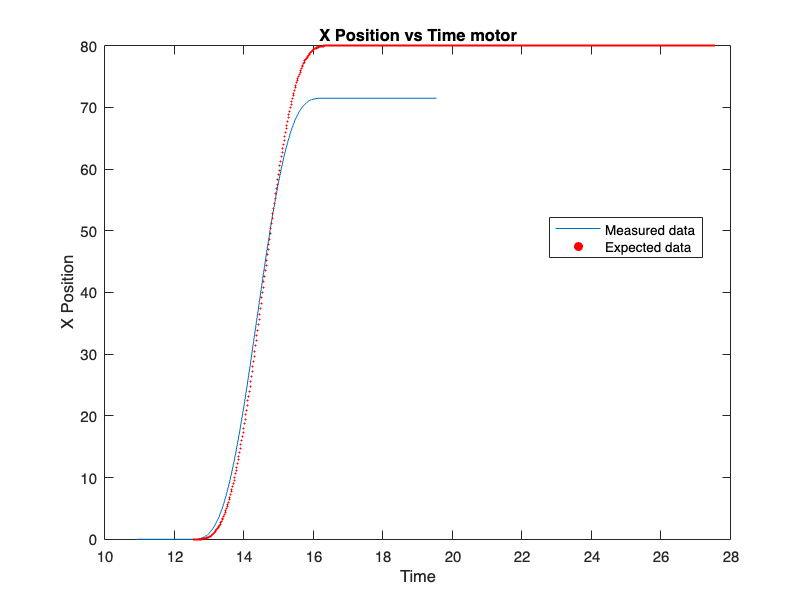

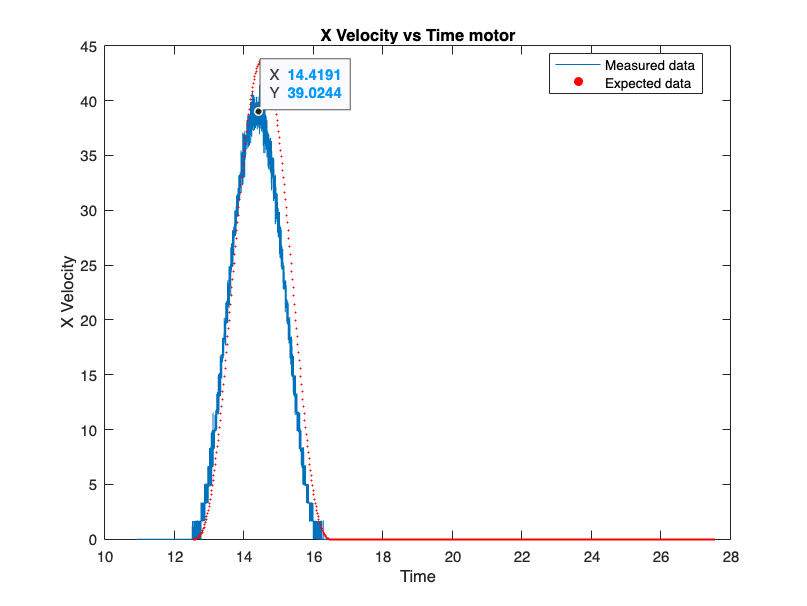

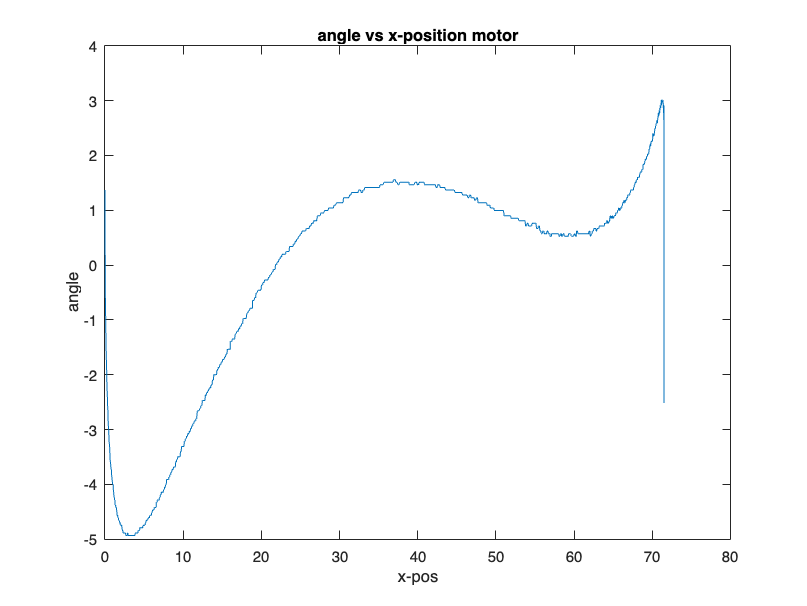

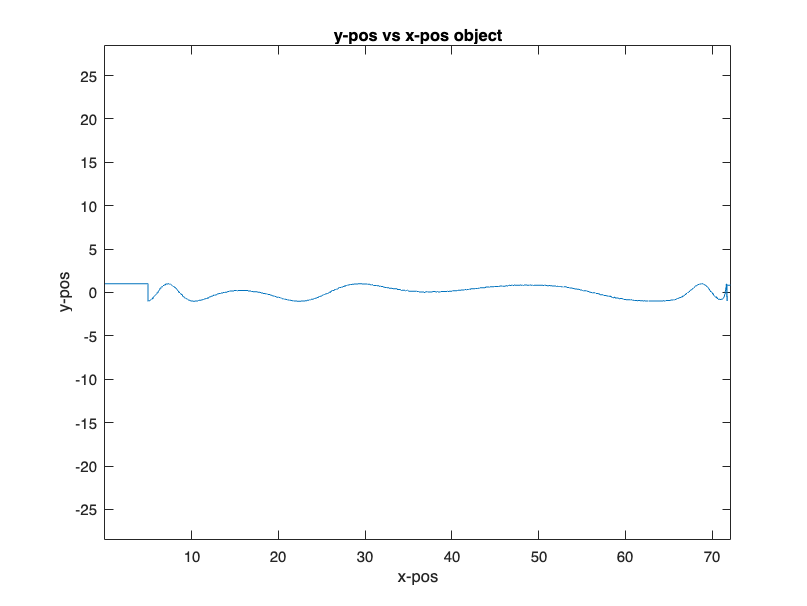


if plot_2 == true  
       % Define the file name
    file_name = 'poly_v02_no_angle.csv';
    
    % Read the CSV file
    data = csvread(file_name, 10000); % Skip the first 6000 rows
    
    % Extract time (1st column) and x position (4th column)
    time =  data(:,1);
    x_position = data(:, 4);
    x_velocity = data(:,5);
    angle = data(:, 15);
    y_position = data(:,6);
    last_zero_index = find(x_position == 0, 1, 'last');
    time_shift = time(last_zero_index);

    
    input_data = csvread("poly_position_old.csv");
    input_time = 1:length(input_data);
    input_position = input_data(1,:);
    input_data = csvread("poly_velocity_old.csv");
    input_velocity = input_data(1,:);


    figure;
    plot(time, x_position);
    xlabel('Time');
    ylabel('X Position');
    hold on 
    scatter(input_time/freq + time_shift, input_position*100, 2, 'r', 'filled');
    hold off
    title('X Position vs Time motor');
    legend('Measured data', 'Expected data', 'Location', 'best');


    figure;
    plot(time, x_velocity);
    xlabel('Time');
    ylabel('X Velocity');
    hold on 
    scatter(input_time/freq + time_shift, input_velocity*100, 2, 'r', 'filled');
    hold off
    title('X Velocity vs Time motor');
    legend('Measured data', 'Expected data', 'Location', 'best');
    
    

    figure
    plot(x_position(last_zero_index:end), angle(last_zero_index:end));
    xlabel('x-pos');
    ylabel('angle');
    title('angle vs x-position motor');
    

    figure
    plot(smoothdata(x_position +sin(angle)), cos(angle));
    xlabel('x-pos');
    ylabel('y-pos');
    title('y-pos vs x-pos object');
    axis equal

end

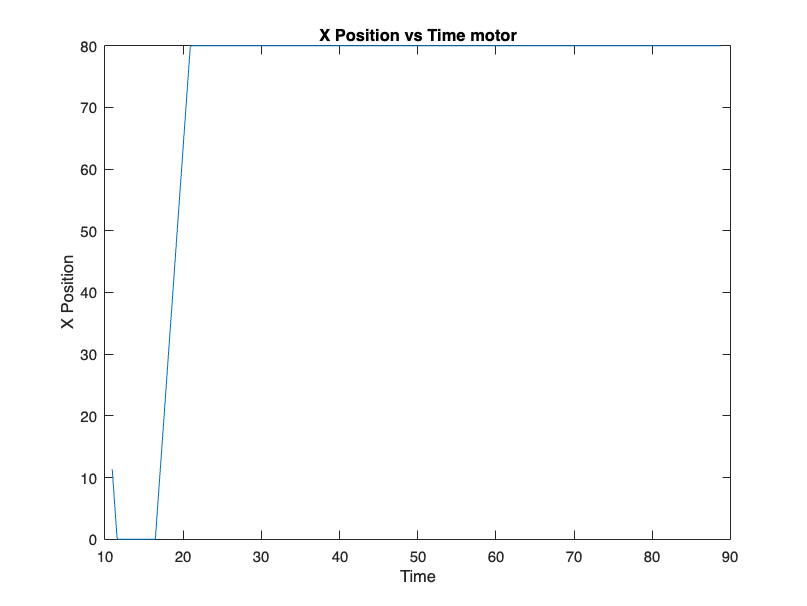

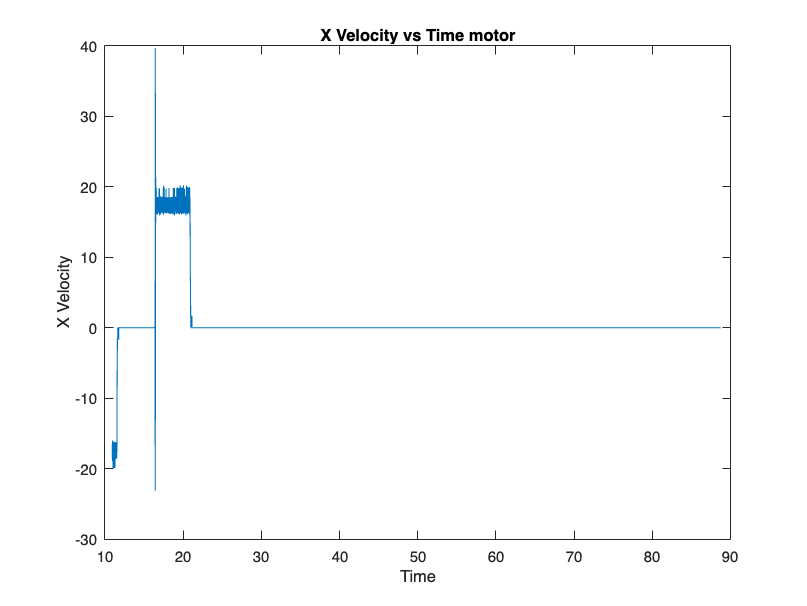

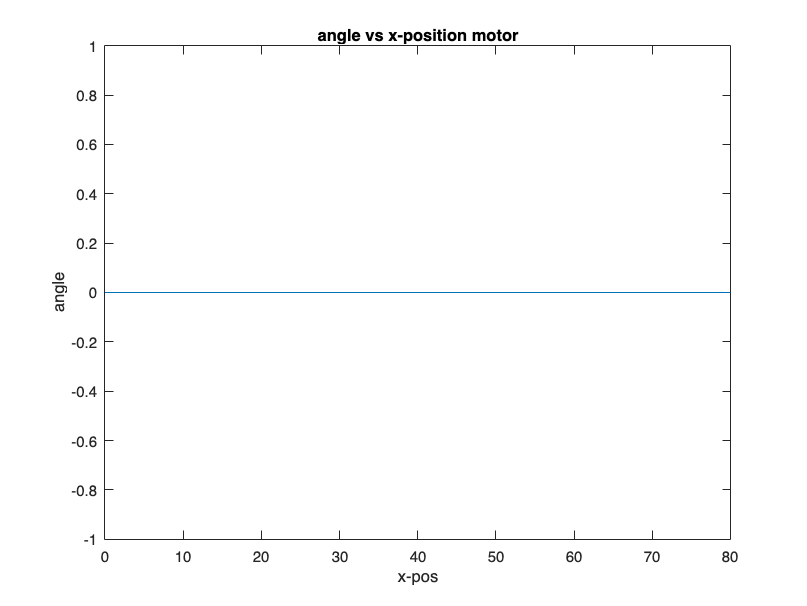

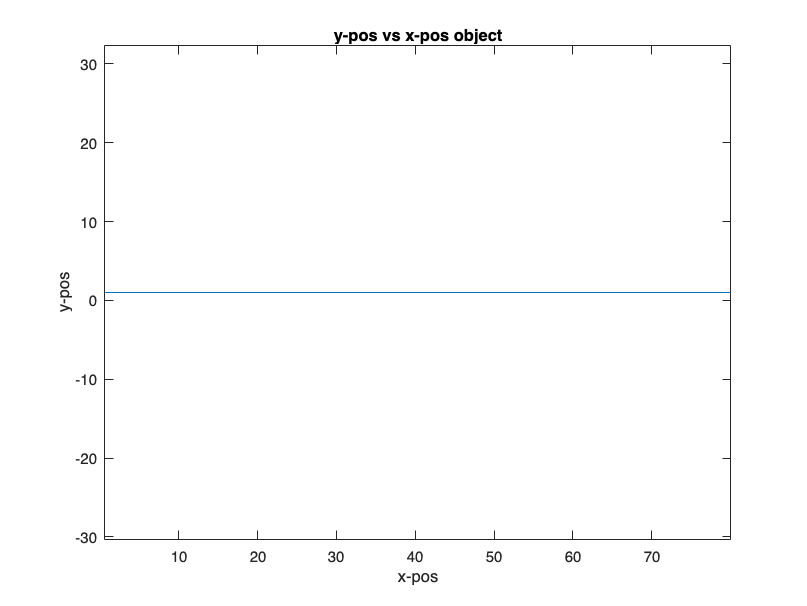



if plot_3 == true  
       % Define the file name
    file_name = 'pickup_with_sleep.csv';
    
    % Read the CSV file
    data = csvread(file_name, 10000); % Skip the first 6000 rows
    
    % Extract time (1st column) and x position (4th column)
    time =  data(:,1);
    x_position = data(:, 4);
    x_velocity = data(:,5);
    angle = data(:, 15);
    y_position = data(:,6);
    last_zero_index = find(x_position == 0, 1, 'last');
    time_shift = time(last_zero_index);

    
    % input_data = csvread("ramp_position.csv");
    % input_time = 1:length(input_data);
    % input_position = input_data(1,:);
    % input_data = csvread("ramp_velocity.csv");
    % input_velocity = input_data(1,:);


    figure;
    plot(time, x_position);
    xlabel('Time');
    ylabel('X Position');
    hold on 
    %scatter(input_time/freq + time_shift, input_position*100, 2, 'r', 'filled');
    hold off
    title('X Position vs Time motor');
    %legend('Measured data', 'Expected data', 'Location', 'best');


    figure;
    plot(time, x_velocity);
    xlabel('Time');
    ylabel('X Velocity');
    hold on 
    %scatter(input_time/freq + time_shift, input_velocity*100, 2, 'r', 'filled');
    hold off
    title('X Velocity vs Time motor');
    %legend('Measured data', 'Expected data', 'Location', 'best');
    
    

    figure
    plot(x_position(last_zero_index:end), angle(last_zero_index:end));
    xlabel('x-pos');
    ylabel('angle');
    title('angle vs x-position motor');
    

    figure
    plot(smoothdata(x_position +sin(angle)), cos(angle));
    xlabel('x-pos');
    ylabel('y-pos');
    title('y-pos vs x-pos object');
    axis equal

    
end